spectral resolution is 1 Hz so the signal has to be T0=1/F0 s long i.e 1/1=1s

clear ylim
% Extract the wanted signal
wanted_duration = 1/spectral_resolution;
nb_samples = round(wanted_duration * fs);

y = y_long(1:nb_samples);
t=0:1/fs:wanted_duration-(1/fs);

Same as multiplying by a rect (window) function with ones everywhere where we want to keep the signal, and zeros everywhere else. The cutting will lead to oscilations in the frequencies plots. 

% make the spectrum function 
function [Y, freq] = make_spectrum(signal, fs)
Y = fft(signal); % compute spectrum (note: it will be complex-valued).
Y = abs(Y/(length(signal))); % The FFT needs to be scaled in order to give a physically plausible scaling.

T0=(length(signal))/fs;
delta_f = 1/T0;
frequneg= (-fs/2)+delta_f:delta_f:-delta_f;
freqpos= 0:delta_f:fs/2;
freq= [freqpos, frequneg];

Y = Y(:);
freq = freq(:);

end

if window=="rect"
    y=y.*rectwin(length(y))';
elseif window=="hann"
    y=y.*hann(length(y))';
elseif window=="hamming" 
    y=y.*hamming(length(y))';
end

% Compute the frequency spectra of the signals
[Y, freqs] = make_spectrum(y, fs);

%make the magnitude spectra in dB
magnitude= abs(Y);
magnitude_dB= 20*log10(magnitude);

Plot the spectra:

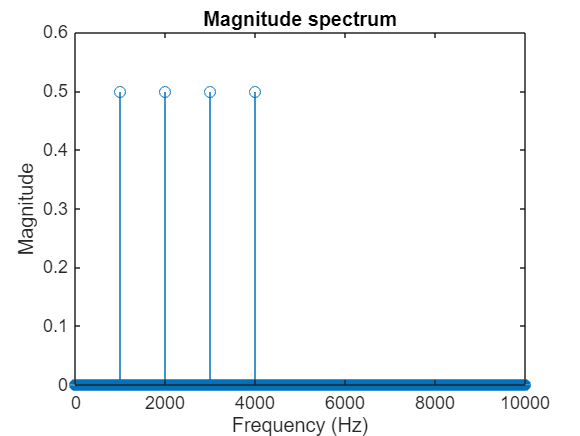

width = 15;
height = 10;
folder_name= '';

% plot the magnitude 
figure(1);
stem(freqs, magnitude)
title('Magnitude spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0, xlimFreq])  ;
ylim=([-ylimFreq, ylimFreq]);

filename = fullfile(folder_name, 'magnitude_spectrum.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');

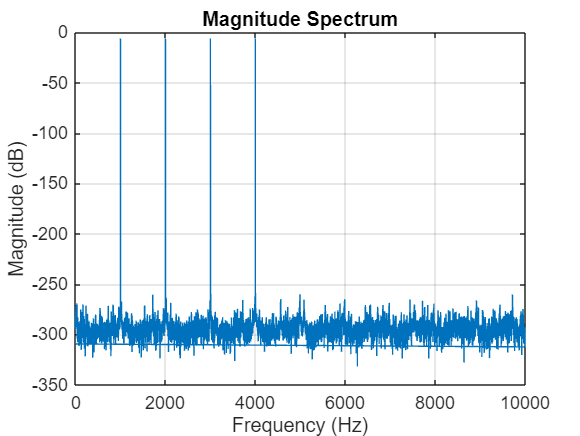


% Plot the magnitude spectrum in dB
figure(2);
plot(freqs, magnitude_dB);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xlim([0, xlimFreq])  ;
ylim=([-ylimFreq, ylimFreq]);

filename = fullfile(folder_name, 'magnitude_spectrum_dB.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');


y=y_long

y =          0    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208


explain limits: nyquist frequency fs/2

STFT:

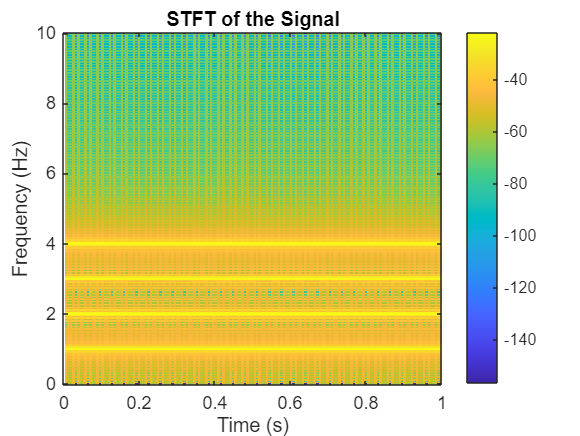

window_length = 256; % Length of each window segment in samples
window_type = rectwin(window_length); % Choose the window type (e.g., hann)
overlap = round(0.5 * window_length); % Set 50% overlap between windows
nfft = 512; % Number of FFT points (determines frequency resolution)

if window=="rect"
    window_type = rectwin(window_length); % Choose the window type (e.g., hann)
elseif window=="hann"
    window_type = hann(window_length); % Choose the window type (e.g., hann)
elseif window=="hamming" 
    window_type =hamming(window_length); % Choose the window type (e.g., hann)
end

% Perform STFT using spectrogram
figure(3);
spectrogram(y, window_type, overlap, nfft, fs, 'yaxis');
title('STFT of the Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
xmin = 0;
xmax = wanted_duration; % Use the duration of the extracted signal
xlim([xmin, xmax]);
ylim=([-ylimFreq, ylimFreq]);
colorbar; % Display colorbar for magnitude scaling

filename = fullfile(folder_name, 'STFT_spectrum.pdf');
% Specify paper properties
set(gcf, 'PaperUnits', 'centimeters'); % Set units to centimeters
set(gcf, 'PaperSize', [width, height]); % Set the paper size
set(gcf, 'PaperPosition', [0, 0, width, height]); % Set the paper position to fill the page
print(gcf, filename, '-dpdf', '-r300');